# Reconocimiento de la nota

Primero leemos cada una de las notas de voz

Fs = 10000;
load Note_1.mat
load Note_2.mat
load Note_3.mat

x1 = Note_1;
x1 = x1 - mean(x1);
N1 = length(x1)

N1 =        16000


t1 = (0:(N1-1))/Fs;
%length(t1), length(x1)

ans =        16000


ans =        16000



x2 = Note_2;
N2 = length(x2);
x2 = x2 - mean(x2);
t2 = (0:(N2 -1))/Fs;
%length(t2), length(x2)

ans =        16000


ans =        16000




x3 = Note_3;
x3 = x3 - mean(x3);
N3 = length(x3);
t3 = (0:(N3-1))/Fs;
%length(t3), length(x3)

ans =        16000


ans =        16000


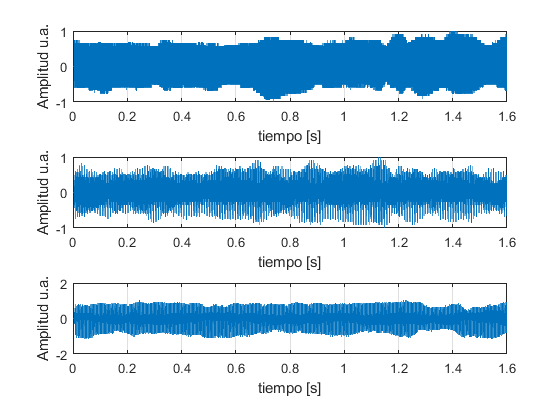

% Graficamos cada señal
subplot(3,1,1)
plot(t1,x1);
xlabel("tiempo [s]")
ylabel("Amplitud u.a.")
grid on

subplot(3,1,2)
plot(t2,x2);
xlabel("tiempo [s]")
ylabel("Amplitud u.a.")
grid on

subplot(3,1,3)
plot(t3,x3);
xlabel("tiempo [s]")
ylabel("Amplitud u.a.")
grid on

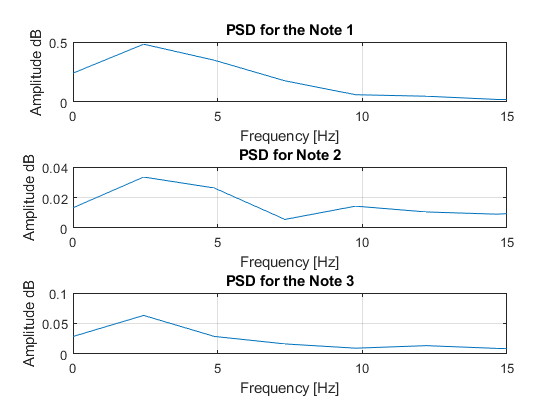

% Calculamos la PSD para cada una de las señales
[Pxx1,F1]= pwelch(x1,[],[],[],Fs,'psd');
Pxx1 = Pxx1*Fs*2*pi; % Converting to normal PSD and not power per rad per sample
subplot(3,1,1)
plot(F1,Pxx1) % Plotting the PSD in a semilog y axis
xlabel('Frequency [Hz]')
ylabel('Amplitude dB')
grid on
xlim([0 max(F)])
title('PSD for the Note 1')


% Computing the PSD
[Pxx2,F2]= pwelch(x2,[],[],[],Fs,'psd');
Pxx2 = Pxx2*Fs*2*pi; % Converting to normal PSD and not power per rad per sample
subplot(3,1,2)
plot(F2,Pxx2) % Plotting the PSD in a semilog y axis
xlabel('Frequency [Hz]')
ylabel('Amplitude dB')
grid on
xlim([0 max(F)])
title('PSD for Note 2')

% Computing the PSD
[Pxx3,F3]= pwelch(x3,[],[],[],Fs,'psd');
Pxx3 = Pxx3*Fs*2*pi; % Converting to normal PSD and not power per rad per sample
subplot(3,1,3)
plot(F3,Pxx3) % Plotting the PSD in a semilog y axis
xlabel('Frequency [Hz]')
ylabel('Amplitude dB')
grid on
xlim([0 max(F)])
title('PSD for the Note 3')


% Calculo de las frecuencias con Amplitud en PSD maxima
max(Pxx1),max(Pxx2),max(Pxx3)

ans =      6.686266911599463e+02


ans =      2.738438900607081e+02


ans =      9.128317999636746e+02
